# 22051 - Covid-19 processing

The disciplines of signal processing and time series analysis are very close to each other. So why not use the current global pandemic and throw the newly acquired knowledge we have on the numbers?

## Load the data

The data is available from the authorities and will be updated continuously. You can download the current data here:

[SSI data source (in Danish)](https://www.ssi.dk/sygdomme-beredskab-og-forskning/sygdomsovervaagning/c/covid19-overvaagning)

For now we use the data of 2020/09/20 and only the numbers per municipality. Let's load and access the data.

**Note: The data format is a bit"clumsy" and we won't work with that extensively - so no reason spending hours on understanding all the details. Please focus on the filtering :-)**

% load the data
dat = readtable(['dat', filesep, 'Municipality_cases_time_series.csv']);


% let's check out what it looks like.
dat(1,:)

ans = 1×98 table
    date_sample    Roskilde    Copenhagen    Aarhus    Frederiksberg    Kalundborg    Middelfart    Gentofte    Solr_d    Aller_d    Drag_r    Helsing_r    Hiller_d    Rudersdal    N_stved    Aalborg    Vallensb_k    Esbjerg    Favrskov    Frederikssund    Fures_    Greve    Holb_k    Kolding    Odense    Silkeborg    Skanderborg    Vejle    Aabenraa    Ballerup    Egedal    Faxe    Fredericia    Faaborg_Midtfy

Select the column number for the municipality your are interested in. We'll also summ all up to get the overall over DK.

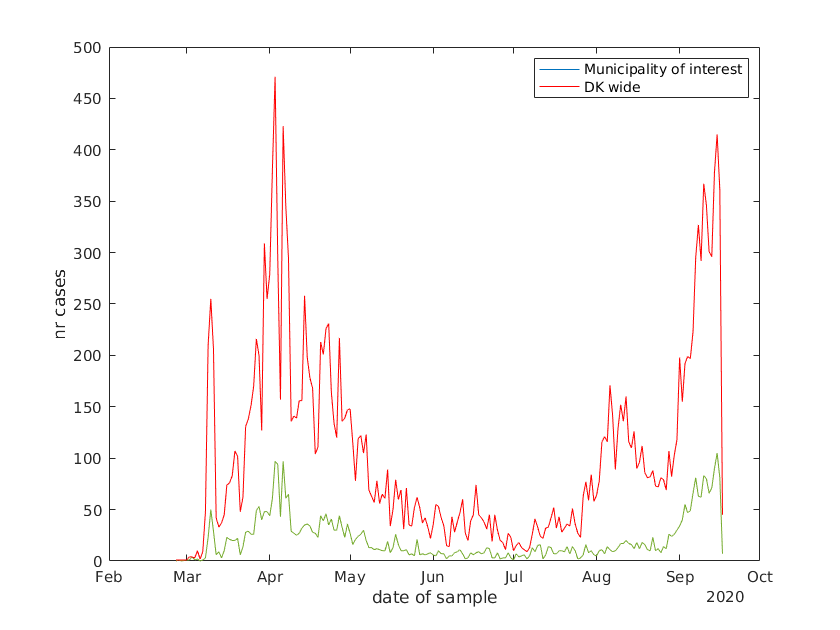

% municipality of interest (moi)
dat_moi = dat.Copenhagen;   % for Copenhagen

% all DK
dat_dk = sum(dat{:,[2:end]},2);

% Let's look at it in a plot
plot(dat.date_sample,dat_moi)
xlabel('date of sample')
ylabel(['nr cases'])

% add all DK data on top
hold on;
plot(dat.date_sample,dat_dk,'r')

% add a legend
legend({'Municipality of interest','DK wide'})

## Moving average filtering

Now we might get started. Let's play with amoving average filter to smoothen the data (these are the plots you see in the media - the often show a nice smooth line on top of the raw data). All we need to do is to consider the number of cases as a signal and define the running sum as a filter by an impulse response.

% Let's just see that it does work with a hardcoded filter. We'll improve that later
h_dumb = [1/3 1/3 1/3];

% let's run the "signal" through the filter

dat_dk_conv = conv(dat_dk,h_dumb);

%plotting
plot(dat_dk_conv)

You can change the impulse repsonse above by another order (make it a week or so).

Try to implement the running sum in a flexible way so you define the order and MATLAB does the rest for you. So you define the order *N *and MATLAB generates a vector of length *N+1* with N elements of value *1/(N+1).*

% define the IR of the running sum.
% NOTE: uncomment below and complete

% N = ;     % define the order
% h = ;     % make a vector of ones andscale by 1(/N+1)

% dat_moi_conv = conv(dat_moi,h);
% dat_dk_conv = conv(dat_dk,h);

% plot!

Wait! I've been talking about "filter coefficients". So why not use a filter function to do that? The syntax of the *filter* commend is as follows:

With *B *being the feed-forward coefficients and A the feed-back coefficients (just add a *1* if you don't have any). So why not try with the filter command?

% NOTE: uncomment below and complete

% dat_moi_filtered = filter( , ,dat_moi);
% dat_dk_filtered = filter( , ,dat_dk);


Plot the result using the *conv *command and using the *filter* command. What do you observe?

..we will continue developing this...